load('magnetic4hz_170928_031259.rhd/magstim.mat')
load('magnetic4hz_170928_031259.rhd/spiketrain.mat')

% load('magnetic_170928_025824.rhd/magstim.mat')
% load('magnetic_170928_025824.rhd/spiketrain.mat')

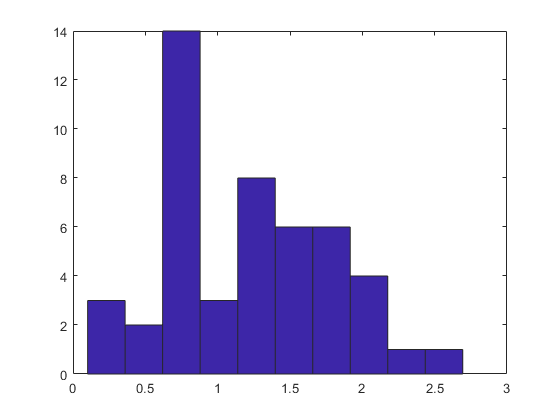

fr=4;
chat=[];
c=[];
x=[];

k=1;
for i=1:size(spiketrain, 2)
    % Get current spiketrain
    st = spiketrain{1,i};
    
    % Filter whole periods
    st = st(st > magstim_trigger(1) & st < magstim_trigger(end));

    if length(st)>100
        
        T = st(end) - st(1);
        j=1;
        for f=3.5:0.01:4.5
            if f==fr
                cs=calculate_coefficient(st,f,T);
            else
                c(j)=calculate_coefficient(st,f,T);
                x(j)=f;
                j=j+1;
            end
        end
        m=mean(abs(c));
        
        chat(k)=abs(cs)/((std(real(c))+std(imag(c)))/2);

        k=k+1;
    end
end

hist(chat)

function c=calculate_coefficient(st,fr,t)
z=0+1i;
c=sum(exp(2*pi*fr*st*z))/t;
end

